# Assignment 10

William Watkins, in collaboration with Addi Woodard and Sarah Foley

18 November, 2019

## Clear the workspace

clear all
close all
clc

## 1. 

Declare constants, retrieve values

global Constants Conv nDLatDer E1
B747LatValues()

Calculate the Body Frame Dimensional Derivatives

DLatDer.v.Y = 0.5  * E1.rho * E1.u0 * E1.S * nDLatDer.Beta.Cy;              % [N*s/m]
DLatDer.v.L = 0.5  * E1.rho * E1.u0 * E1.b * E1.S * nDLatDer.Beta.Cl;       % [N/s]
DLatDer.v.N = 0.5  * E1.rho * E1.u0 * E1.b * E1.S * nDLatDer.Beta.Cn;       % [N/s]

DLatDer.p.Y = 0.25 * E1.rho * E1.u0 * E1.b * E1.S * nDLatDer.pHat.Cy;       % [N*s/rad]
DLatDer.p.L = 0.25 * E1.rho * E1.u0 * (E1.b)^2 * E1.S * nDLatDer.pHat.Cl;   % [N*m*s/rad]
DLatDer.p.N = 0.25 * E1.rho * E1.u0 * (E1.b)^2 * E1.S * nDLatDer.pHat.Cn;   % [N*m*s/rad]

DLatDer.r.Y = 0.25 * E1.rho * E1.u0 * E1.b * E1.S * nDLatDer.rHat.Cy;       % [N*s/rad]
DLatDer.r.L = 0.25 * E1.rho * E1.u0 * (E1.b)^2 * E1.S * nDLatDer.rHat.Cl;   % [N*m*s/rad]
DLatDer.r.N = 0.25 * E1.rho * E1.u0 * (E1.b)^2 * E1.S * nDLatDer.rHat.Cn;   % [N*m*s/rad]

% Values calculated above
disp(DLatDer.v)

    Y: -1.0772e+04
    L: -2.0487e+05
    N: 1.4254e+05



disp(DLatDer.p)

    Y: 0
    L: -7.1974e+06
    N: -8.8969e+05



disp(DLatDer.r)

    Y: 0
    L: 6.6404e+06
    N: -5.9720e+06



Calculate the Stability Frame Dimensional Derivatives, from (B.12, 7), page 356

StabDer.v.Y = DLatDer.v.Y;
StabDer.v.L = DLatDer.v.L * cosd(E1.Xi) - DLatDer.v.N * sind(E1.Xi);
StabDer.v.N = DLatDer.v.N * cosd(E1.Xi) + DLatDer.v.L * sind(E1.Xi);

StabDer.p.Y = DLatDer.p.Y * cosd(E1.Xi) - DLatDer.r.Y * sind(E1.Xi);
StabDer.p.L = DLatDer.p.L * cosd(E1.Xi)^2 - (DLatDer.r.L + DLatDer.p.N) * ...
    sind(E1.Xi) * cosd(E1.Xi) + DLatDer.r.N * sind(E1.Xi)^2;
StabDer.p.N = DLatDer.p.N * cosd(E1.Xi)^2 - (DLatDer.r.N - DLatDer.p.L) * ...
    sind(E1.Xi) * cosd(E1.Xi) - DLatDer.r.L * sind(E1.Xi)^2;

StabDer.r.Y = DLatDer.r.Y * cosd(E1.Xi) + DLatDer.p.Y * sind(E1.Xi);
StabDer.r.L = DLatDer.r.L * cosd(E1.Xi)^2 - (DLatDer.r.N - DLatDer.p.L) * ...
    sind(E1.Xi) * cosd(E1.Xi) - DLatDer.p.N * sind(E1.Xi)^2;
StabDer.r.N = DLatDer.r.N * cosd(E1.Xi)^2 + (DLatDer.r.L + DLatDer.p.N) * ...
    sind(E1.Xi) * cosd(E1.Xi) + DLatDer.p.L * sind(E1.Xi)^2;

Calculate primed moments of inertia from (4.9, 19), page 113

IPrime.x = (E1.Ix * E1.Iz - E1.Izx ^2) / E1.Iz;
IPrime.z = (E1.Ix * E1.Iz - E1.Izx ^2) / E1.Ix;
IPrime.zx = E1.Izx / ()

## 2.

Create the lateral A matrix, (4.9,19), page 113

Alat = zeros(4, 4);

Alat(1, 1) = StabDer.v.Y / E1.m;
Alat(1, 2) = StabDer.p.Y / E1.m;
Alat(1, 3) = ((StabDer.r.Y / E1.m) - E1.u0);
Alat(1, 4) = Constants.g * cosd(E1.theta0);

Alat(2, 1) = ((StabDer.v.L / E1.Ix) + E1.Izx * StabDer.v.N);
Alat(2, 2) = ((StabDer.p.L / E1.Ix) + E1.Izx * StabDer.p.N);
Alat(2, 3) = ((StabDer.r.L / E1.Ix) + E1.Izx * StabDer.r.N);
Alat(2, 4) = 0;

Alat(3, 1) = (E1.Izx * StabDer.v.L + (StabDer.v.N / E1.Iz));
Alat(3, 2) = (E1.Izx * StabDer.p.L + (StabDer.p.N / E1.Iz));
Alat(3, 3) = (E1.Izx * StabDer.r.L + (StabDer.r.N / E1.Iz));
Alat(3, 4) = 0;

Alat(4, 1) = 0;
Alat(4, 2) = 1;
Alat(4, 3) = tand(E1.theta0);
Alat(4, 4) = 0;

## 3.

Determine eigenvectors and eigenvalues of the lateral A matrix

[V, D] = eig(Alat) % returns a vector containing the eigenvectors, and a vector

V =    -0.0000   -0.0000    0.9997   -0.9282
   -0.4664   -0.8440   -0.0057    0.0053
    0.8846   -0.5364    0.0247   -0.0229
   -0.0000    0.0000    0.0014   -0.3714


D = 	1.0e+13 *

    1.3724         0         0         0
         0   -0.6161         0         0
         0         0   -0.0000         0
         0         0         0   -0.0000


% containing the eigenvalues along the diagonal
D = diag(D); % Eigenvalues are extracted from the diagonal

Plot eigenvalues!

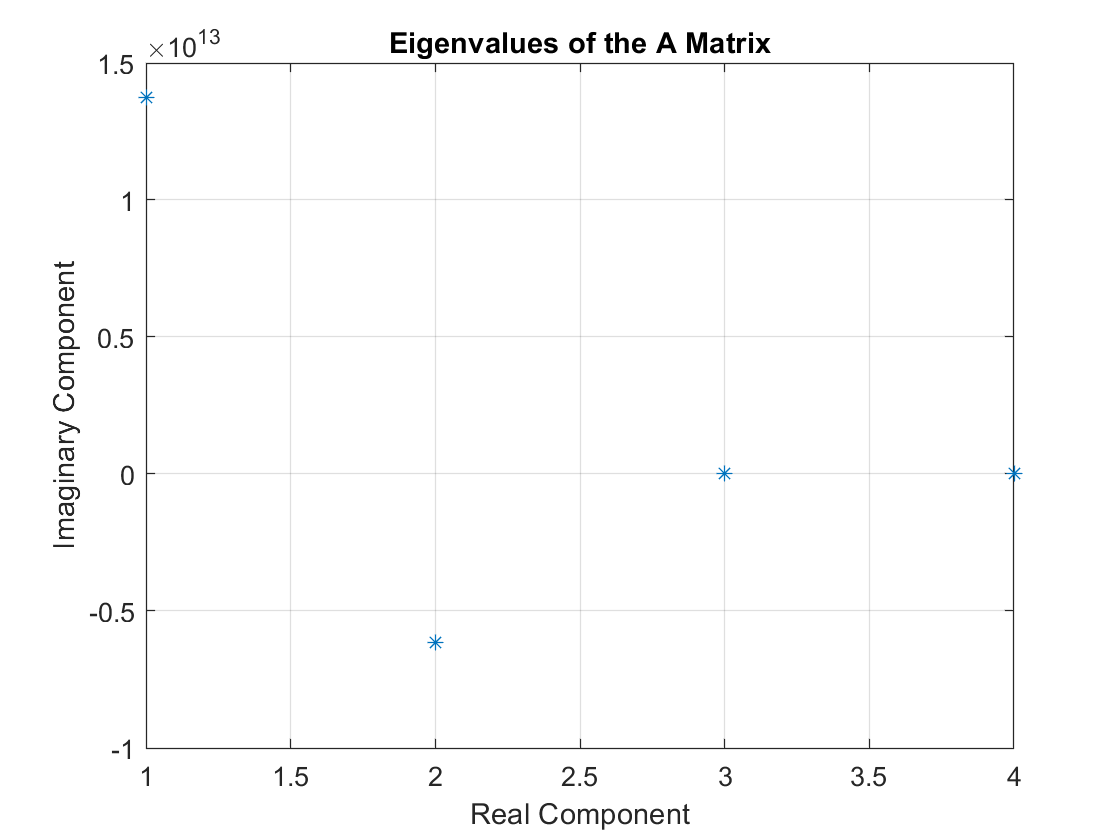

figure()
plot(D,'*')
hold on
title('Eigenvalues of the A Matrix')
grid on
xlabel('Real Component')
ylabel('Imaginary Component')
hold off

%{
t = linspace(0,30,3000);
figure()
hold on
y1 = exp(real(D(1) .* t)) .* cos(imag(D(1) .* t)); % Short Period, positive imaginary
y2 = exp(real(D(1) .* t)) .* sin(imag(D(1) .* t)); % Short Period, negative imaginary
y3 = exp(real(D(3) .* t)) .* cos(imag(D(3) .* t)); % Phugoid, pos imaginary
y4 = exp(real(D(3) .* t)) .* sin(imag(D(3) .* t)); % Phugoid, neg imaginary
plot(t, y1);
plot(t, y2);
plot(t, y3);
plot(t, y4);
legend('-.4619+.9284i','-.4619-.9284i','-.0020+.0822i','-.0020-.0822i','Location','best')
title('Response Time of Eigenvalues for A Matrix')
xlabel('Time [s]')
hold off
t = 0;
%}